clearvars; close all; clc;

syms p q;

fs = 250;           % Sample frequency
N = 3000;           % Data length
t = (-N:N)/fs;      % Time scale
s = 0.01:0.1:2;     % Values of scaling factor

wavelet=zeros(length(t),length(s));
wavelet_mean = zeros(1,length(s));
wavelet_energy = zeros(1,length(s));

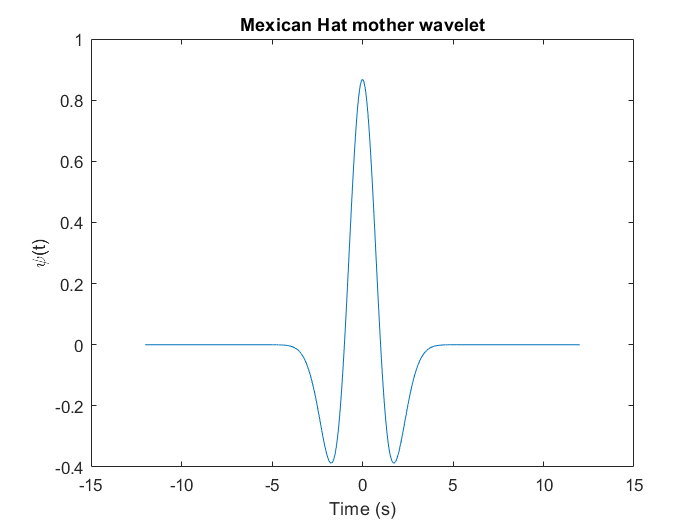

% Maxican hat wavelet
% 1.1
%1.2.1, 1.2.2
mother_wavelet = (2/((3^0.5)*(pi^0.25)))*(1-t.^2).*exp(-(t.^2)/2);

figure('Name', 'Mexican Hat mother wavelet');
plot(t,mother_wavelet);
title('Mexican Hat mother wavelet');
xlabel('Time (s)');
ylabel('\psi(t)');

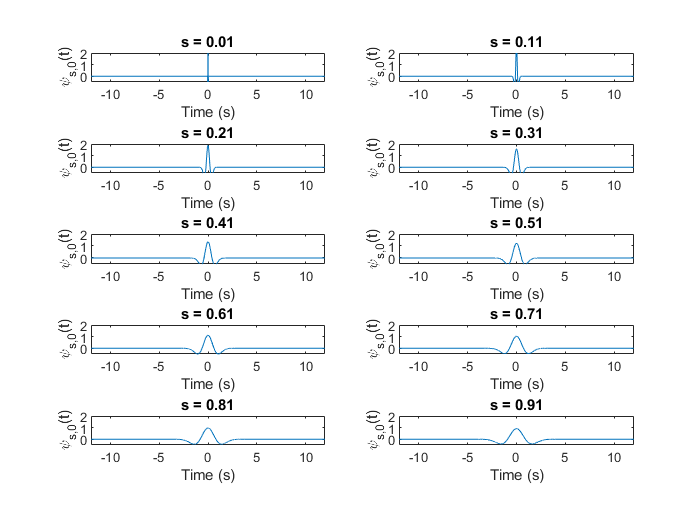

% 1.2.4
% Daughter wavelets are plotted in two different figures
% So figures are clear

figure ('Name','Mexican Hat daughter wavelets');
for scale = 1:10
    wavelet(:,scale) = (2/(((3*s(scale))^0.5)*(pi^0.25)))*(1-(t/s(scale)).^2).*exp((-1/2)*(t/s(scale)).^2);
    
    subplot(5,2,scale);
    plot(t, wavelet(:,scale));
    axis([-12 12 -0.5 2]);
    
    title(['s = ', num2str(s(scale))]);
    xlabel('Time (s)');
    ylabel('\psi_{s,0}(t)');
    
    % Calculating the mean for a given scaling factor
    wavelet_mean(scale) = int((2/((sqrt(3*s(scale)))*(pi^(1/4))))*(1-((p/s(scale)).^2)).*exp((-1/2)*(p/s(scale)).^2), 'p', -inf, inf);
    % Calculating the energy for a given scaling factor
    wavelet_energy(scale) =  int(((2/((sqrt(3*s(scale)))*(pi^(1/4))))*(1-((q/s(scale)).^2)).*exp((-1/2)*(q/s(scale)).^2))^2, 'q', -inf, inf);
end

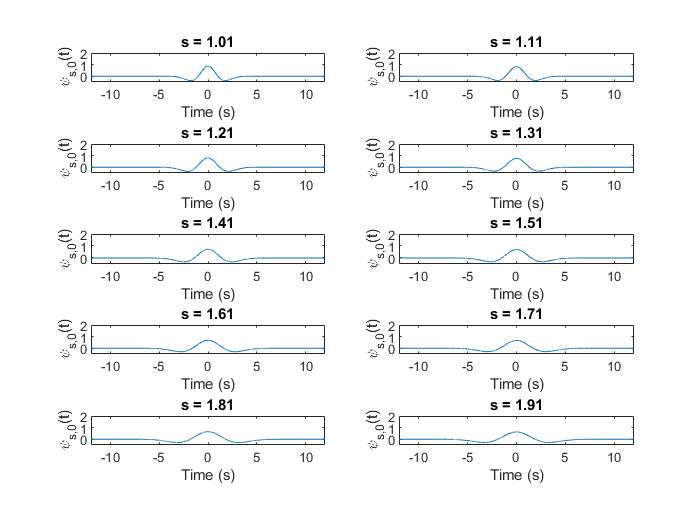

for scale = 11:20
    wavelet(:,scale) = (2/(((3*s(scale))^0.5)*(pi^0.25)))*(1-(t/s(scale)).^2).*exp((-1/2)*(t/s(scale)).^2);
    
    subplot(5,2,scale-10);
    plot(t, wavelet(:,scale));
    axis([-12 12 -0.5 2]);
    
    title(['s = ', num2str(s(scale))]);
    xlabel('Time (s)');
    ylabel('\psi_{s,0}(t)');
    
    % Calculating the mean for a given scaling factor
    wavelet_mean(scale) = int((2/((sqrt(3*s(scale)))*(pi^(1/4))))*(1-((p/s(scale)).^2)).*exp((-1/2)*(p/s(scale)).^2), 'p', -inf, inf);
    % Calculating the energy for a given scaling factor
    wavelet_energy(scale) =  int(((2/((sqrt(3*s(scale)))*(pi^(1/4))))*(1-((q/s(scale)).^2)).*exp((-1/2)*(q/s(scale)).^2))^2, 'q', -inf, inf);
end

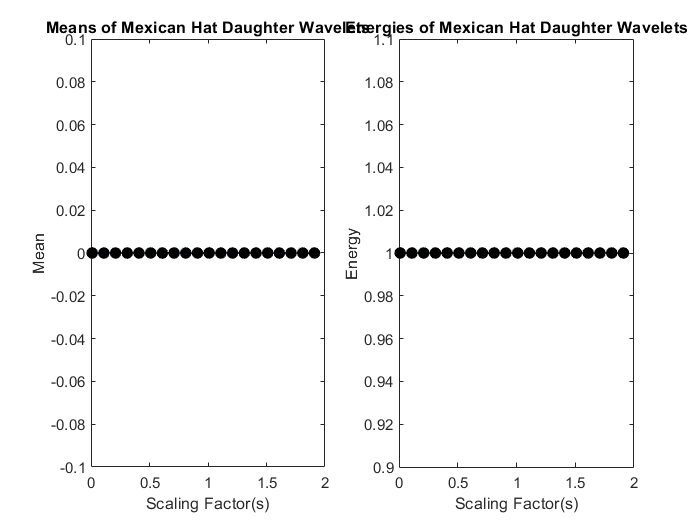

%1.2.5

figure ('Name','Means and Energies of Mexican Hat Daughter Wavelets');

subplot(1,2,1);
plot(s, wavelet_mean,'-o', 'LineWidth',1,'MarkerEdgeColor','k','MarkerFaceColor','k');
axis([0 2 -0.1 0.1]);
title('Means of Mexican Hat Daughter Wavelets');
xlabel('Scaling Factor(s)');
ylabel('Mean');

subplot(1,2,2);
plot(s, wavelet_energy,'-o', 'LineWidth',1, 'MarkerEdgeColor','k','MarkerFaceColor','k');
axis([0 2 0.9 1.1])
title('Energies of Mexican Hat Daughter Wavelets');
xlabel('Scaling Factor(s)');
ylabel('Energy');

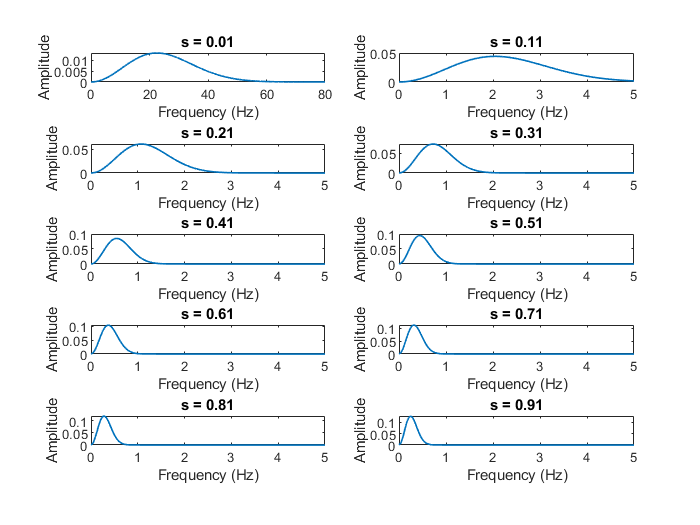

%1.2.6

figure ('Name' , 'Spectra of Wavelets')

for val = 1:length(s)/2
    Fwavelt = fft(wavelet(:,val))/length(wavelet(:,val));
    hz = linspace(0,fs/2,floor(length(wavelet(:,val))/2)+1);
    
    subplot(5,2,val);
    plot(hz, 2*abs(Fwavelt(1:length(hz))), 'LineWidth',1)
    title(['s = ', num2str(s(val))]);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    xlim([0,5])
end
subplot(5,2,1);
xlim([0,80])

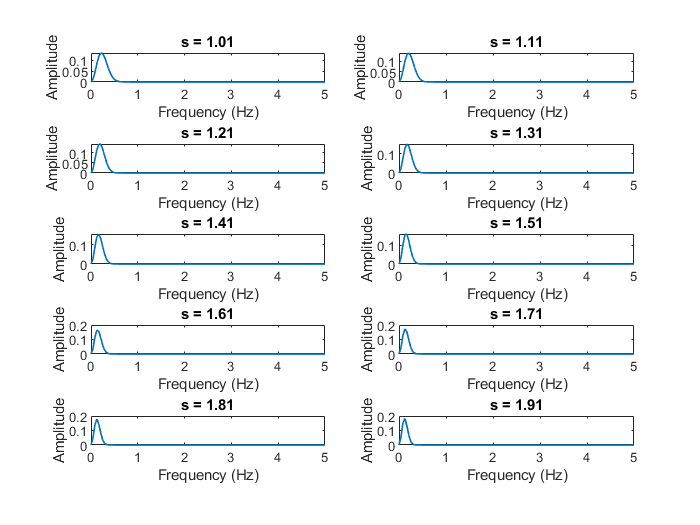


figure ('Name' , 'Spectra of Wavelets')

for val = length(s)/2 +1:length(s)
    Fwavelt = fft(wavelet(:,val))/length(wavelet(:,val));
    hz = linspace(0,fs/2,floor(length(wavelet(:,val))/2)+1);
    
    subplot(5,2,val- length(s)/2);
    plot(hz, 2*abs(Fwavelt(1:length(hz))), 'LineWidth',1)
    xlim([0,5])
    title(['s = ', num2str(s(val))]), xlabel('Frequency (Hz)'), ylabel('Amplitude')
end

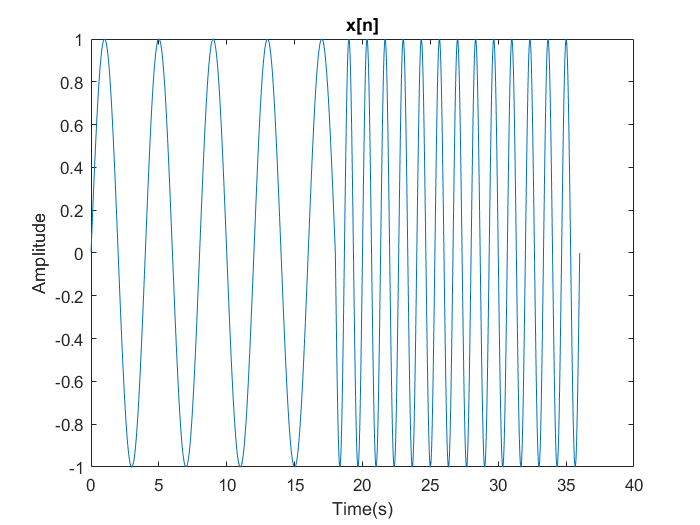

%1.3
%1.3.1

n1=1:3*N/2-1;
n2=3*N/2:3*N;
n=[n1 n2];
xn1=sin(0.5*pi*n1/fs);
xn2=sin(1.5*pi*n2/fs);
xn=[xn1 xn2];
figure('Name','Wave form x[n]');
plot(n/fs,xn);
title('x[n]');
xlabel('Time(s)');
ylabel('Amplitude')

%1.3.2
s_new = 0.01:0.01:2; 

convolved_entries = zeros(length(s_new), length(n));

for val = 1:length(s_new)
    wavelet_for_val = (2/(((3*s_new(val))^0.5)*(pi^0.25)))*(1-(t/s_new(val)).^2).*exp((-1/2)*(t/s_new(val)).^2);
    % Convolution
    conv_sig = conv(xn, wavelet_for_val);  
    
    redundant_component = floor(length(wavelet_for_val)/2); 
    convolved_entries(val,:) = conv_sig(redundant_component+1: length(conv_sig) - redundant_component); 
end

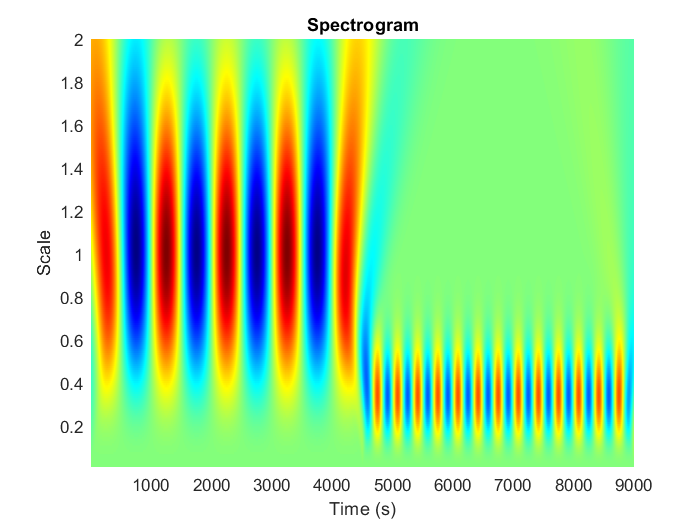


% 1.3.3 Visualizing the Spectrogram

h = pcolor(n, s_new, convolved_entries);
set(h, 'EdgeColor', 'none');
colormap jet
xlabel('Time (s)')
ylabel('Scale')
title('Spectrogram')